clear
addpath control_clasic
load("trajectories.mat");
modelName = 'CONTROL_CLASSIC';

load_system(modelName);
out = sim(modelName);

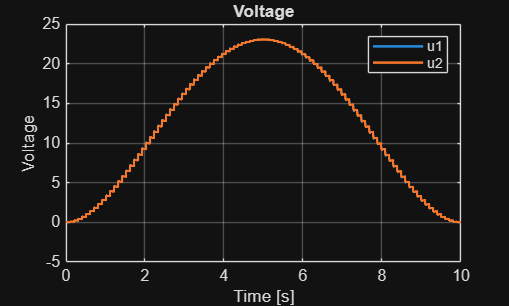

voltage  = out.voltage;
errors_Q  = out.errors_Q;
torque   = out.torque;

voltage_data = squeeze(voltage.Data);
errors_Q_data = squeeze(errors_Q.Data);
torque_data  = squeeze(torque.Data);

figure
plot(voltage.Time, voltage_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Voltage')
title('Voltage')
legend('u1', 'u2')

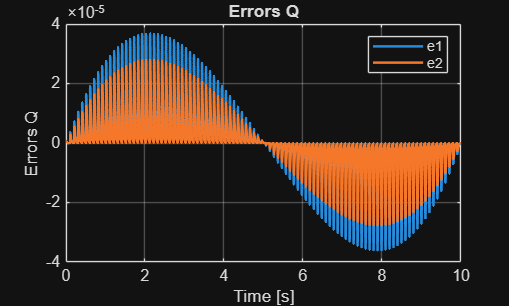


figure
plot(errors_Q.Time, errors_Q_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Errors Q')
title('Errors Q')
legend('e1', 'e2')

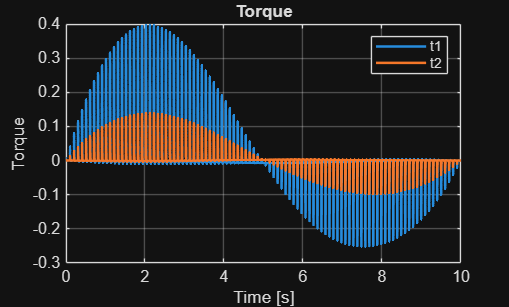


figure
plot(torque.Time, torque_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Torque')
title('Torque')
legend('t1', 't2')